Backtracking Algorithm:

function [x] = gradient_method_backtracking(f, g, x0, s, alpha, beta, epsilon, z)
    % Gradient method with backtracking stepsize rule
    %
    % INPUT
    % =======================================
    % f ......... objective function
    % g ......... gradient of the objective function
    % x0......... initial point
    % s ......... initial choice of stepsize
    % alpha ..... tolerance parameter for the stepsize selection
    % beta ...... the constant in which the stepsize is multiplied
    %             at each backtracking step (0 < beta < 1)
    % epsilon ... tolerance parameter for stopping rule
    %
    % OUTPUT
    % =======================================
    % x ......... optimal solution (up to a tolerance)
    %             of min f(x)
    % fun_val ... optimal function value

    x = x0;
    iter_gm = 0;
    
    while iter_gm < 500
        
        iter_gm = iter_gm + 1;
        t = s;
        
        % Backtracking line search
        while (f(x, z) - f(x - t * g(x, z), z) < alpha * t * norm(g(x, z))^2)
            t = beta * t;
        end
        x_new = x - t * g(x, z);


        % Display iteration details
        fprintf('gradient_iter_number = %3d norm_grad = %2.6f fun_val = %2.6f\n', iter_gm, norm(g(x, z)), f(x, z));

        % compare x
        if norm(x_new - x) / norm(x_new) < epsilon
            break;
        end
        x = x_new;
        
    end
end

Inputs & parameters:

% Import data from file
f_data = readmatrix('noisy_signal.csv');

% parameters
n = 1000;
L = diag(ones(n, 1), 0) - diag(ones(n-1, 1), 1);
L = 999 * L(1:end-1, :);
A_bar = eye(n, 2*n-1);
L_bar = [-L, eye(n-1)];
lambda = 5 * 10^(-4);
gamma = 10^(3);
omega_bar = [zeros(1, n), 75 * ones(1, n-1)];

u = [f_data; zeros(999, 1)];   % self-defined
X = u(1:1000)

X =     0.9938
    0.8729
    1.0139
    0.9902
    0.9902
    0.9847
    0.9436
    1.0097
    0.9696
    0.9586


y = u(1001:1999)

y =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


z = L * X - y;
s = 1;   % self-defined
alpha = 0.5;   % self-defined
beta = 0.5;   % self-defined
epsilon = 10^-4;

% Define function h & approximated ||1 norm
h_gamma = @(t) ...
    (abs(t) <= 1/gamma) .* (gamma * t.^2 / 2) + ...
    (abs(t) > 1/gamma) .* (abs(t) - 1/(2 * gamma));

% Define gradient of approximated norm l1
gradient_l1_norm = @(u) ...
    omega_bar' .* (abs(u) <= 1/gamma) .* gamma .* u + ...
    omega_bar' .* (abs(u) > 1/gamma) .* sign(u);

% Define objective function
objective_function = @(u, z) ...
    0.5 * norm(A_bar * u - f_data)^2 + ...
    0.5 * lambda * norm(L_bar * u - z)^2 + ...
    omega_bar * h_gamma(u);

% Define gradient of the objective function
grad = @(u, z) ...
    A_bar' * (A_bar * u - f_data) + ...
    lambda * L_bar' * (L_bar * u - z) + ...
    gradient_l1_norm(u);

Backtracking Function Call & Timer:

tic;
iter_full = 0

iter_full = 0

while iter_full < 1 || norm(X - X_prev) / norm(X) > 10^(-5)
    tic;
    u = gradient_method_backtracking(objective_function, grad, u, s, alpha, beta, epsilon, z);
    elapsedTime_gm = toc;  % Measure elapsed time
    fprintf('Gradient method took %.4f seconds to execute.\n', elapsedTime_gm);
    X_prev = X
    X = u(1:1000)
    y = u(1001:1999)
    z = z + (L * X - y)
    iter_full = iter_full + 1
end

gradient_iter_number =   1 norm_grad = 106716.738679 fun_val = 550031.847594
gradient_iter_number =   2 norm_grad = 33244.960481 fun_val = 175756.949761
gradient_iter_number =   3 norm_grad = 28802.691041 fun_val = 125744.641191
gradient_iter_number =   4 norm_grad = 28050.142936 fun_val = 123772.999182
gradient_iter_number =   5 norm_grad = 21070.893195 fun_val = 122590.948929
gradient_iter_number =   6 norm_grad = 27887.390150 fun_val = 108387.647658
gradient_iter_number =   7 norm_grad = 27069.700510 fun_val = 100925.151704
gradient_iter_number =   8 norm_grad = 26040.989242 fun_val = 97534.077526
gradient_iter_number =   9 norm_grad = 23990.603898 fun_val = 95831.325138
gradient_iter_number =  10 norm_grad = 15439.014323 fun_val = 95054.108668
gradient_iter_number =  11 norm_grad = 23848.452726 fun_val = 93930.600748
gradient_iter_number =  12 norm_grad = 15350.698538 fun_val = 93149.738573
gradient_iter_number =  13 norm_grad = 23741.853048 fun_val = 92171.178912
gradient_iter_num

Gradient method took 94.3692 seconds to execute.


X_prev =     0.9938
    0.8729
    1.0139
    0.9902
    0.9902
    0.9847
    0.9436
    1.0097
    0.9696
    0.9586


X =     0.9405
    1.0640
    0.9277
    0.9568
    0.9618
    0.9714
    1.0159
    0.9527
    0.9955
    1.0094


y = 1.0e-03 *

   -0.3799
    0.2403
   -0.2078
   -0.5598
    0.5123
    0.4921
    0.4727
   -0.5666
    0.1268
    0.5259


z = 1.0e+03 *

   -0.0027
   -0.0047
   -0.0053
   -0.0050
   -0.0041
   -0.0033
   -0.0029
   -0.0028
   -0.0028
   -0.0029


iter_full = 1

gradient_iter_number =   1 norm_grad = 53681.654068 fun_val = 190730.519538
gradient_iter_number =   2 norm_grad = 37423.641318 fun_val = 130138.739372
gradient_iter_number =   3 norm_grad = 32549.759400 fun_val = 116058.321372
gradient_iter_number =   4 norm_grad = 31105.686585 fun_val = 110698.827979
gradient_iter_number =   5 norm_grad = 28088.974781 fun_val = 107755.551457
gradient_iter_number =   6 norm_grad = 21211.672963 fun_val = 106568.305308
gradient_iter_number =   7 norm_grad = 26890.730767 fun_val = 98828.532959
gradient_iter_number =   8 norm_grad = 25650.130961 fun_val = 95637.841579
gradient_iter_number =   9 norm_grad = 22770.054878 fun_val = 93997.649354
gradient_iter_number =  10 norm_grad = 14204.603633 fun_val = 93324.125956
gradient_iter_number =  11 norm_grad = 22938.314775 fun_val = 92500.932046
gradient_iter_number =  12 norm_grad = 13812.241544 fun_val = 91803.284241
gradient_iter_number =  13 norm_grad = 17055.787093 fun_val = 91325.751682
gradient_iter_numbe

Gradient method took 46.7131 seconds to execute.


X_prev =     0.9405
    1.0640
    0.9277
    0.9568
    0.9618
    0.9714
    1.0159
    0.9527
    0.9955
    1.0094


X =     0.9819
    0.9791
    0.9746
    0.9712
    0.9712
    0.9743
    0.9783
    0.9813
    0.9829
    0.9838


y =    -0.0006
   -0.0001
    0.0006
    0.0003
    0.0003
   -0.0001
    0.0002
   -0.0003
   -0.0005
   -0.0000


z = 1.0e+03 *

    0.0001
   -0.0002
   -0.0019
   -0.0050
   -0.0072
   -0.0073
   -0.0059
   -0.0044
   -0.0038
   -0.0046


iter_full = 2

gradient_iter_number =   1 norm_grad = 11365.948314 fun_val = 123024.183540
gradient_iter_number =   2 norm_grad = 8098.053159 fun_val = 122883.646938
gradient_iter_number =   3 norm_grad = 10006.864100 fun_val = 122712.333879
gradient_iter_number =   4 norm_grad = 7705.500032 fun_val = 122589.176813
gradient_iter_number =   5 norm_grad = 15805.157107 fun_val = 122339.213366
gradient_iter_number =   6 norm_grad = 8148.821427 fun_val = 122168.200764
gradient_iter_number =   7 norm_grad = 10394.271188 fun_val = 122012.296095
gradient_iter_number =   8 norm_grad = 7650.202616 fun_val = 121887.315789
gradient_iter_number =   9 norm_grad = 9200.594455 fun_val = 121723.925753
gradient_iter_number =  10 norm_grad = 7328.134007 fun_val = 121613.928023
gradient_iter_number =  11 norm_grad = 14046.168226 fun_val = 121358.402284
gradient_iter_number =  12 norm_grad = 7685.380298 fun_val = 121220.810104
gradient_iter_number =  13 norm_grad = 9536.762676 fun_val = 121070.572261
gradient_iter_number

Gradient method took 51.5986 seconds to execute.


X_prev =     0.9819
    0.9791
    0.9746
    0.9712
    0.9712
    0.9743
    0.9783
    0.9813
    0.9829
    0.9838


X =     0.9790
    0.9789
    0.9789
    0.9788
    0.9779
    0.9768
    0.9769
    0.9786
    0.9814
    0.9844


y = 1.0e-03 *

    0.5812
    0.0979
   -0.5773
   -0.2966
   -0.2521
    0.1293
   -0.2019
    0.3066
    0.5138
    0.0318


z = 1.0e+03 *

    0.0003
   -0.0003
   -0.0018
   -0.0041
   -0.0061
   -0.0074
   -0.0076
   -0.0072
   -0.0067
   -0.0061


iter_full = 3

gradient_iter_number =   1 norm_grad = 10033.824497 fun_val = 157540.292447


Gradient method took 0.4611 seconds to execute.


X_prev =     0.9790
    0.9789
    0.9789
    0.9788
    0.9779
    0.9768
    0.9769
    0.9786
    0.9814
    0.9844


X =     0.9790
    0.9789
    0.9789
    0.9788
    0.9779
    0.9768
    0.9769
    0.9786
    0.9814
    0.9844


y = 1.0e-03 *

    0.5812
    0.0979
   -0.5773
   -0.2966
   -0.2521
    0.1293
   -0.2019
    0.3066
    0.5138
    0.0318


z = 1.0e+03 *

    0.0005
   -0.0003
   -0.0017
   -0.0032
   -0.0051
   -0.0074
   -0.0093
   -0.0101
   -0.0097
   -0.0077


iter_full = 4

% Display iteration details
    fprintf('full_iter_number = %3d', iter_full);

full_iter_number =   4


elapsedTime = toc;  % Measure elapsed time
fprintf('Function took %.4f seconds to execute.\n', elapsedTime);

Function took 0.4755 seconds to execute.


plot

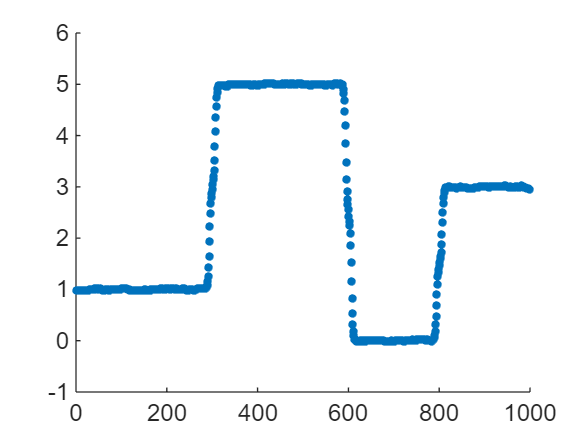

% Plot the denoised data
scatter(1:length(X), X, 10, 'filled');



% full algorithm: 8
% each gradient method: 100, 48, 79, 26, 27, 68, 37, 1
% 
% execution time: 150.9539 seconds